# Communicate with the TurtleBot

This example introduces the TurtleBot® platform and the ways in which MATLAB® users can interact with it. Specifically, the code in this example demonstrates how to publish messages to the TurtleBot (such as velocities) and how to subscribe to topics that the TurtleBot publishes (such as odometry).

*The TurtleBot must be running for this example to work.*

[Gazebo 및 Simulated TurtleBot 시작하기 - MATLAB & Simulink (mathworks.com)](https://www.mathworks.com/help/ros/ug/get-started-with-gazebo-and-a-simulated-turtlebot.html)

[https://emanual.robotis.com/docs/en/platform/turtlebot3/quick-start/](https://emanual.robotis.com/docs/en/platform/turtlebot3/quick-start/)

[https://emanual.robotis.com/docs/en/platform/turtlebot3/simulation/](https://emanual.robotis.com/docs/en/platform/turtlebot3/simulation/)

참고하십시오

Prerequisites: [Get Started with Gazebo and a Simulated TurtleBot](docid:ros_ug.mw_9c45a664-ab3d-48a5-a65a-52913b8532b5) or [Get Started with a Real TurtleBot](docid:ros_ug.mw_c9b2d3c3-0e9c-4222-8294-1453212e9813)

## Connect to the TurtleBot

The TurtleBot must be running*.* If you are using a real TurtleBot and followed the hardware setup steps in [Get Started with a Real TurtleBot](docid:ros_ug.mw_c9b2d3c3-0e9c-4222-8294-1453212e9813), the robot is running. If you are using a TurtleBot in simulation and followed the setup steps in [Get Started with Gazebo and a Simulated TurtleBot](docid:ros_ug.mw_9c45a664-ab3d-48a5-a65a-52913b8532b5), launch one of the Gazebo® worlds from the desktop (`Gazebo Office`, for instance). 

TurtleBot이 실행 중이어야 합니다. 실제 TurtleBot을 사용 중이고 실제 TurtleBot 시작하기의 하드웨어 설정 단계를 따랐다면 로봇이 실행되고 있는 것입니다. 시뮬레이션에서 TurtleBot을 사용하고 Gazebo 및 시뮬레이션된 TurtleBot 시작하기의 설정 단계를 따랐다면 데스크탑에서 Gazebo® 세계 중 하나를 시작하십시오(예: Gazebo Office).

In your MATLAB instance on the host computer, run the following command. Replace `ipaddress` with the IP address of the TurtleBot. This line initializes ROS and connects to the TurtleBot. 

호스트 컴퓨터의 MATLAB 인스턴스에서 다음 명령을 실행합니다. ipaddress를 TurtleBot의 IP 주소로 바꿉니다. 이 라인은 ROS를 초기화하고 TurtleBot에 연결합니다.

%ipaddress = "http://192.168.178.133:11311";
ipaddress = "http://192.168.242.128:11311";
rosinit(ipaddress)

The global ROS node is already initialized and connected to the master at URI "http://192.168.242.128:11311". If you want to restart the global node, call "rosshutdown" first.

If the network you are using to connect to the TurtleBot is not your default network adapter, you can manually specify the IP address of the adapter that is used to connect to the robot. This might happen if you use a Wireless network, but also have an active Ethernet connection. Replace `IP_OF_TURTLEBOT` with the IP address of the TurtleBot and `IP_OF_HOST_COMPUTER` with the IP address of the host adapter that is used to connect to the robot:

Display all the available ROS topics using:

If you do not see any topics, then the network has not been set up properly. Refer to the beginning of this document for network setup steps.

## Move the Robot

You can control the movement of the TurtleBot by publishing a message to the `/cmd_vel` topic. The message has to be of type `geometry_msgs/Twist`, which contains data specifying desired linear and angular velocities. The TurtleBot's movements can be controlled through two different values: the linear velocity along the *X*-axis controls forward and backward motion and the angular velocity around the *Z*-axis controls the rotation speed of the robot base.

/cmd_vel 주제에 메시지를 게시하여 TurtleBot의 움직임을 제어할 수 있습니다. 메시지는 원하는 선형 및 각 속도를 지정하는 데이터가 포함된 geometry_msgs/Twist 유형이어야 합니다. TurtleBot의 움직임은 두 가지 다른 값을 통해 제어할 수 있습니다. X축을 따른 선형 속도는 전진 및 후진 동작을 제어하고 Z축 주위의 각속도는 로봇 베이스의 회전 속도를 제어합니다.

Set a variable `velocity` to use for a brief TurtleBot movement.

짧은 TurtleBot 움직임에 사용할 가변 속도를 설정합니다.

velocity = 0.1;     % meters per second

Create a publisher for the `/cmd_vel` topic and the corresponding message containing the velocity values. Use the publisher with structure format messages for better performance.

/cmd_vel 주제에 대한 게시자와 속도 값이 포함된 해당 메시지를 만듭니다. 더 나은 성능을 위해 구조 형식 메시지와 함께 게시자를 사용하십시오.

robotCmd = rospublisher("/cmd_vel","DataFormat","struct") ;
velMsg = rosmessage(robotCmd);

Set the forward velocity (along the *X*-axis) of the robot based on the `velocity` variable and publish the command to the robot. Let it move for a moment, and then bring it to a stop.

속도 변수를 기반으로 로봇의 전진 속도(X축을 따라)를 설정하고 로봇에 명령을 게시합니다. 잠시 움직이게 한 다음 정지시키십시오.

velMsg.Linear.X = velocity;
send(robotCmd,velMsg)
pause(4)
velMsg.Linear.X = 0;
send(robotCmd,velMsg)

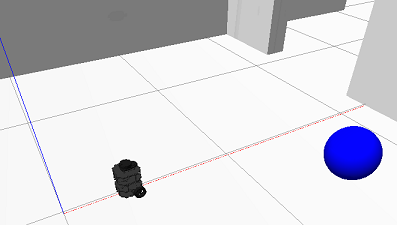

To view the type of the message published by the velocity topic, execute the following:

속도 주제에 의해 게시된 메시지 유형을 보려면 다음을 실행합니다.

rostopic type /cmd_vel

geometry_msgs/Twist


The topic expects messages of type `geometry_msgs/Twist`, which is exactly the type of the `velMsg` created above.

이 주제는 위에서 생성한 velMsg의 유형인 geometry_msgs/Twist 유형의 메시지를 예상합니다.

To view which nodes are publishing and subscribing to a given topic, use the command: [`rostopic`](docid:ros_ref.bupf5_j_14)` info TOPICNAME`. The following command lists the publishers and subscribers for the velocity topic. MATLAB is listed as one of the publishers.

주어진 주제를 발행하고 구독하는 노드를 보려면 rostopic info TOPICNAME 명령을 사용하십시오. 다음 명령은 속도 주제에 대한 게시자 및 구독자를 나열합니다. MATLAB은 게시자 중 하나로 나열됩니다.

  rostopic info /cmd_vel

Type: geometry_msgs/Twist
 
Publishers:
* /matlab_global_node_64350 (http://192.168.242.1:58566/)
 
Subscribers:
* /gazebo (http://192.168.242.128:46707/)


## Receive Robot Position and Orientation

The TurtleBot uses the `/odom` topic to publish its current position and orientation (collectively denoted as pose). Since the TurtleBot is not equipped with a GPS system, the pose will be relative to the pose that the robot had when it was first turned on. 

TurtleBot은 /odom 주제를 사용하여 현재 위치와 방향(집합적으로 포즈로 표시됨)을 게시합니다. TurtleBot에는 GPS 시스템이 장착되어 있지 않기 때문에 포즈는 로봇이 처음 켜졌을 때의 포즈를 기준으로 합니다.

Create a subscriber for the odometry messages

주행 거리 측정 메시지에 대한 구독자 만들기

odomSub = rossubscriber("/odom","DataFormat","struct");

Wait for the subscriber to return data, then extract the data and assign it to variables `x`, `y`, and `z`:

구독자가 데이터를 반환할 때까지 기다린 다음 데이터를 추출하고 변수 x, y 및 z에 할당합니다.

odomMsg = receive(odomSub,3);
pose = odomMsg.Pose.Pose;
x = pose.Position.X;
y = pose.Position.Y;
z = pose.Position.Z;

**Note:** If you see an error, then it is likely that the `receive` command timed out. Make sure that odometry is being published and that your network is set up properly.

Display the *x*, *y*, and *z *values

[x y z]

ans =    -4.5137    0.9107   -0.0010


The orientation of the TurtleBot is stored as a quaternion in the `Orientation` property of `pose`. Use [`quat2eul`](docid:robotics_ref.buofjpw) to convert into the more convenient representation of Euler angles. To display the current orientation, `theta`, of the robot in degrees, execute the following lines.

TurtleBot의 방향은 포즈의 Orientation 속성에 쿼터니언으로 저장됩니다. quat2eul을 사용하여 보다 편리한 오일러 각도 표현으로 변환합니다. 로봇의 현재 방향(ta)을 도 단위로 표시하려면 다음 행을 실행하십시오.

quat = pose.Orientation;
angles = quat2eul([quat.W quat.X quat.Y quat.Z]);
theta = rad2deg(angles(1))

theta = 0.2360

## Receive Lidar Data

Lidar 데이터 수신

Subscribe to the lidar topic:

lidarSub = rossubscriber("/scan","DataFormat","struct");

After subscribing to the lidar topic, wait for the data and then display it with rosPlot.

라이더 주제를 구독한 후 데이터를 기다렸다가 rosPlot으로 표시합니다

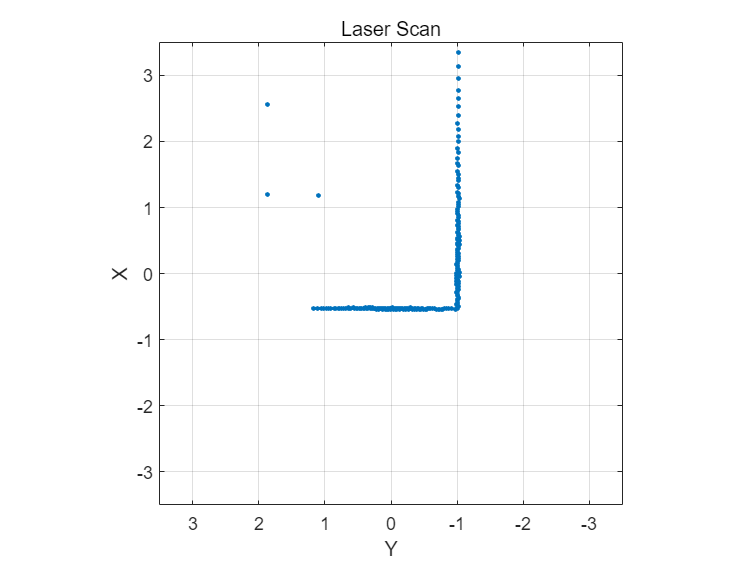

scanMsg = receive(lidarSub);
figure
rosPlot(scanMsg)

To continuously display updating lidar scans while the robot turns for a short duration, use the following while loop:

로봇이 짧은 시간 동안 회전하는 동안 업데이트된 라이다 스캔을 계속 표시하려면 다음 while 루프를 사용하십시오.

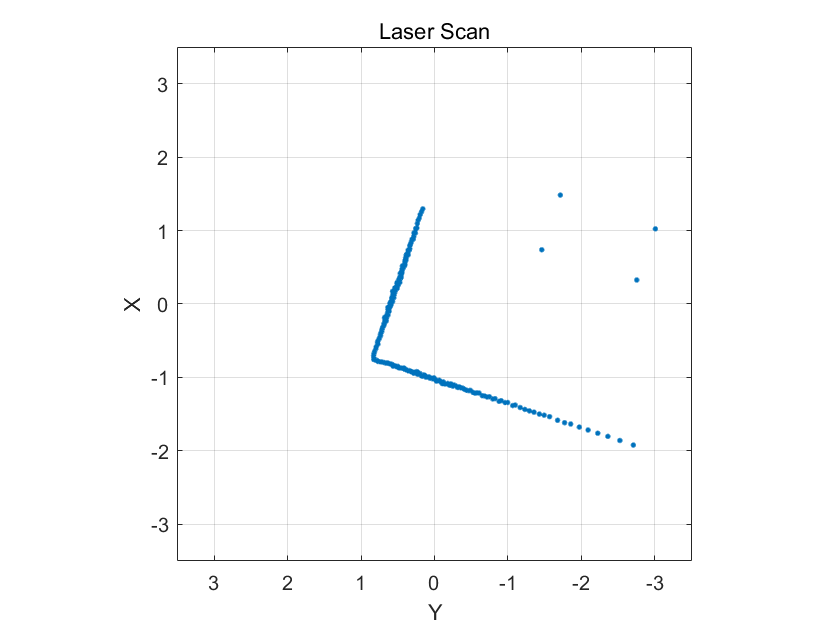

velMsg.Angular.Z = velocity;
send(robotCmd,velMsg)
tic
while toc < 20
  scanMsg = receive(lidarSub);
  rosPlot(scanMsg)
end

velMsg.Angular.Z = 0;
send(robotCmd,velMsg)

## Disconnect from the Robot

Clear the workspace of publishers, subscribers, and other ROS-related objects when you are finished with them.

게시자, 구독자 및 기타 ROS 관련 개체 작업이 끝나면 작업 공간을 지웁니다.

clear

Use [`rosshutdown`](docid:ros_ref.bupf5_j_8) once you are done working with the ROS network. Shut down the global node and disconnect from the TurtleBot.

ROS 네트워크 작업이 끝나면 rosshutdown을 사용하십시오. 전역 노드를 종료하고 TurtleBot에서 연결을 끊습니다.

rosshutdown

Shutting down global node /matlab_global_node_64350 with NodeURI http://192.168.242.1:58566/ and MasterURI http://192.168.242.128:11311.


## Next Steps

Refer to the next example: [Explore Basic Behaviour of the TurtleBot](docid:ros_ug.mw_953f208b-5f53-47e8-bcfd-cb43f322e5ff)

*Copyright 2014-2021 The MathWorks, Inc.*